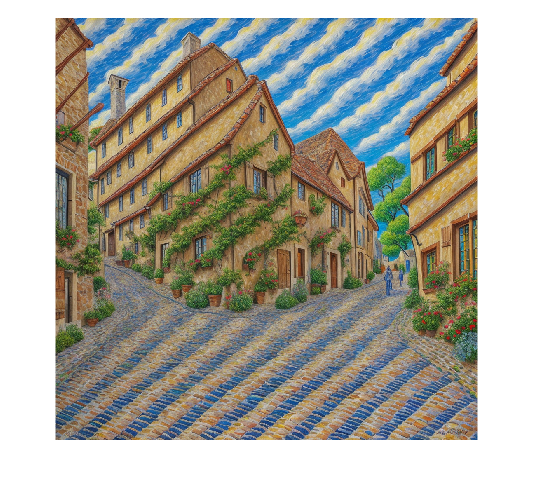

im = double(imread("wave.png"))/255; %исходный массив 
im_f = fftshift(fft2(im)); %фурье образ
module = log(1+abs(im_f)); %нормализовали логарифм от модуля
module = (module-min(module(:)))/(max(module(:))-min(module(:)));
argum = angle(im_f); %аргумент образа
imwrite(module,"wave_f.png");

imshow("wave.png")

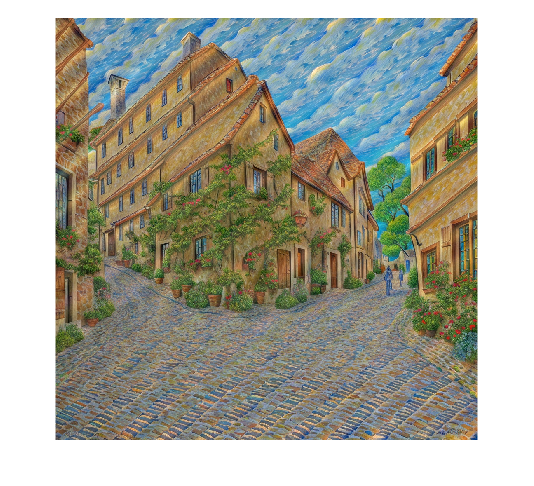

im_f_new = double(imread('wave_f_new.png'))/255;

module_new = exp(im_f_new * log(1 + max(abs(im_f(:)))));
im_new = ifft2(ifftshift(module_new .* exp(1i*argum)));

imwrite(real(im_new), 'wave_new.png');
imshow("wave_new.png")


% Сохранение восстановленного изображения
